**1.    Analyse von Merkmalen, gradientenbasierte Segmentierung (60-90 Min)**

- Zu sehen ist ein Bild mit zu segmentierenden Objekten. Notieren Sie zu jedem Objekt mögliche Merkmale die zur Segmentierung verwendet werden können. Welches sind die aus Ihrer Sicht die jeweils herausstechendsten Merkmale? Begründen Sie.

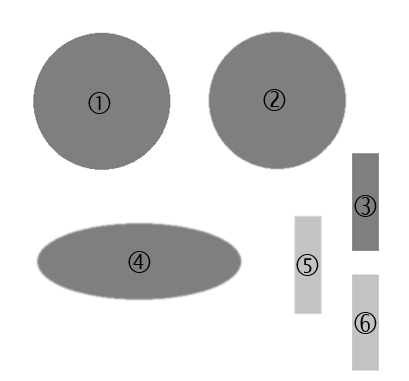

- Erstellen Sie mithilfe der Funktion `imbinarize` ein Script, das eine Segmentierung der Objekte 1 und 3 ermöglicht. Warum ist hier eine Segmentierung allein mit einem Schwellwert nicht möglich? 

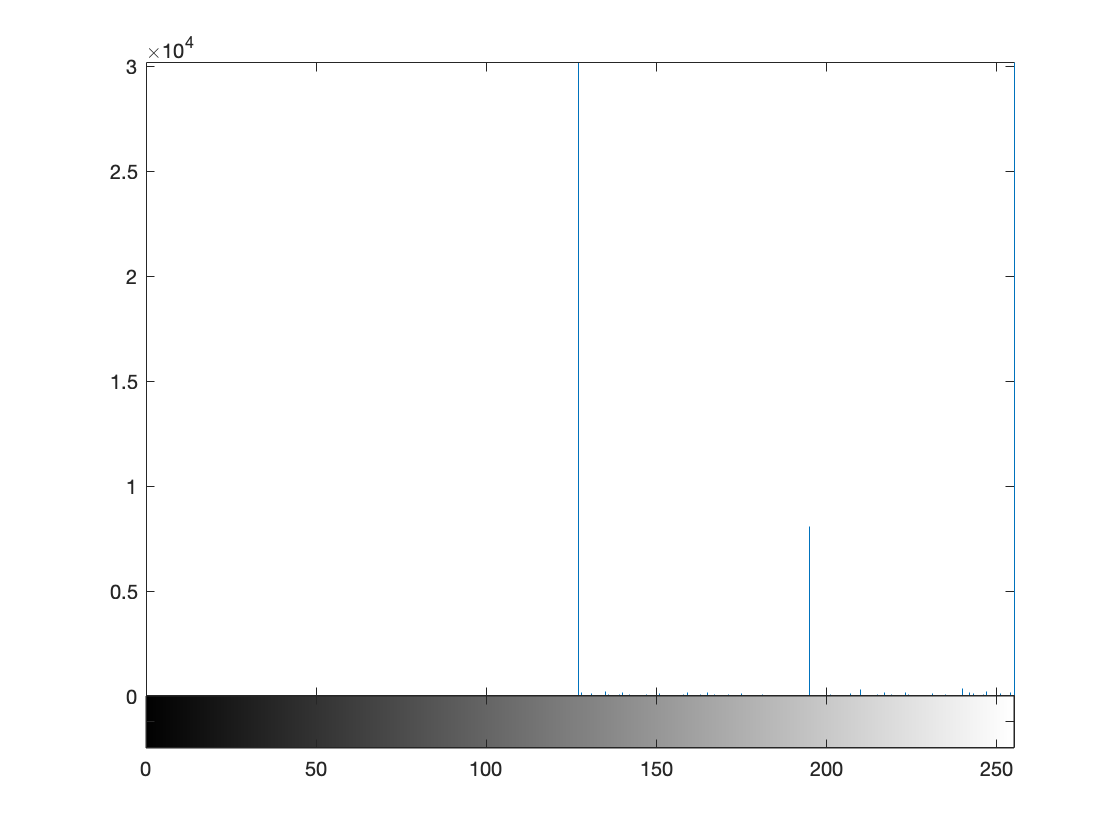

 %%sinnvolle Segmentierungseigenschaften
 %Durchmesser,Form,Grauwert,Position
 %Achsenlängen, Verhältnis der Achsenlänge
 %Länge, Breite, Diagonale, Grauwert, Position

 img1=imread("/Users/tonystark/Desktop/TUB 2. Semester/BGA/Matlab-Files-20210107/Bild_Formen.png");
 img1_bin=imbinarize(img1,150/255);
 imhist(img1);

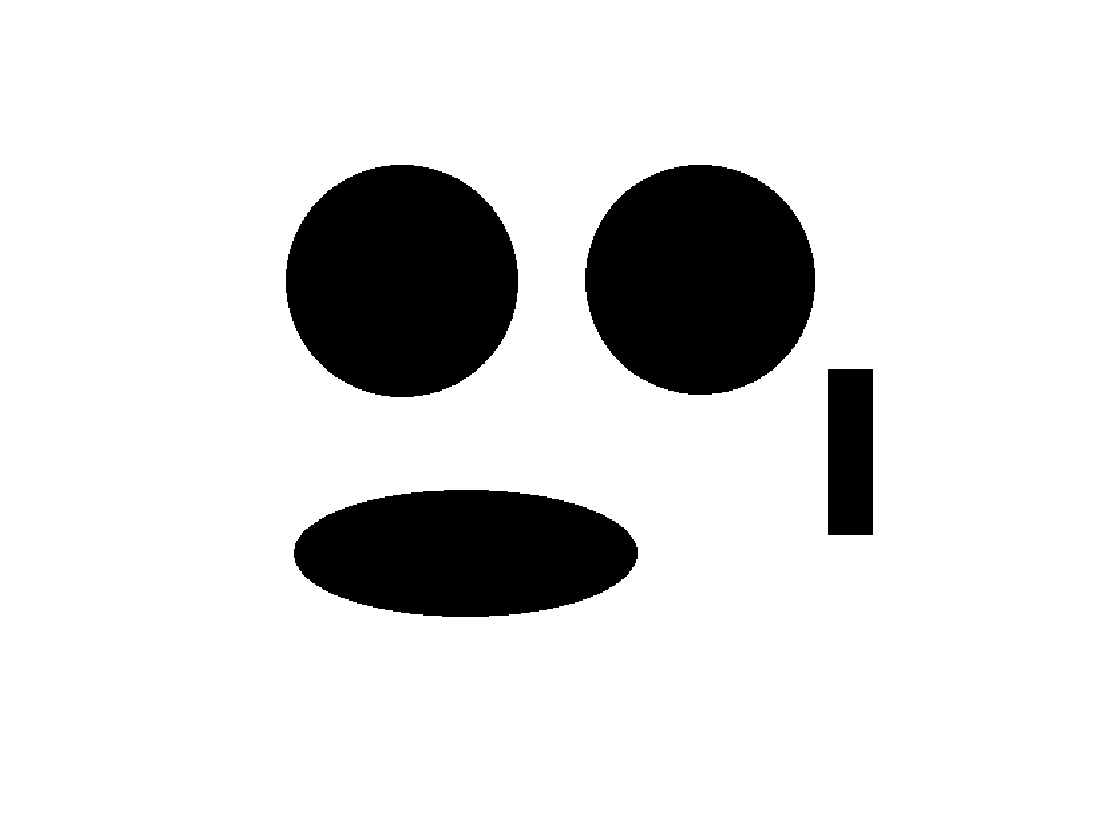

 imshow(img1_bin)

- Verwenden Sie die Funktion `imgradientxy` zur Berechnung der Richtungsgradienten in X- und Y-Richtung. Stellen Sie die berechneten Bilder nebeneinander dar. Berechnen Sie aus diesen Bildern mit `imgradient` das Betrags- und das Richtungsbild und stellen Sie diese ebenfalls nebeneinander dar.

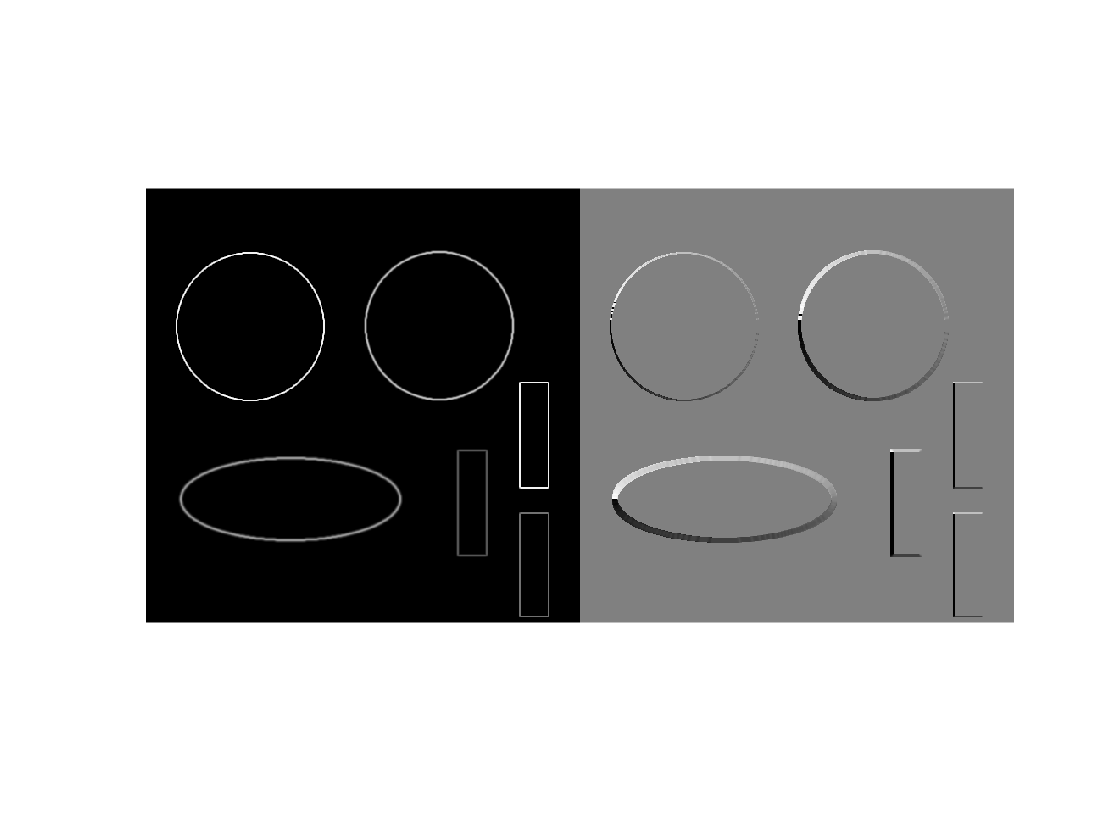

[S_grx1,S_gry1]=imgradientxy(img1,"prewitt"); %using sobel method

%Gmagnite und Gdirection Ableiten
[Gm,Gd]=imgradient(S_grx1,S_gry1);
imshowpair(Gm,Gd,"montage");

- Segmentieren Sie anhand des Betragsbildes die Objekte 1 und 3. Stellen Sie es als ausgefüllte Kontur dar (`imfill`*)*

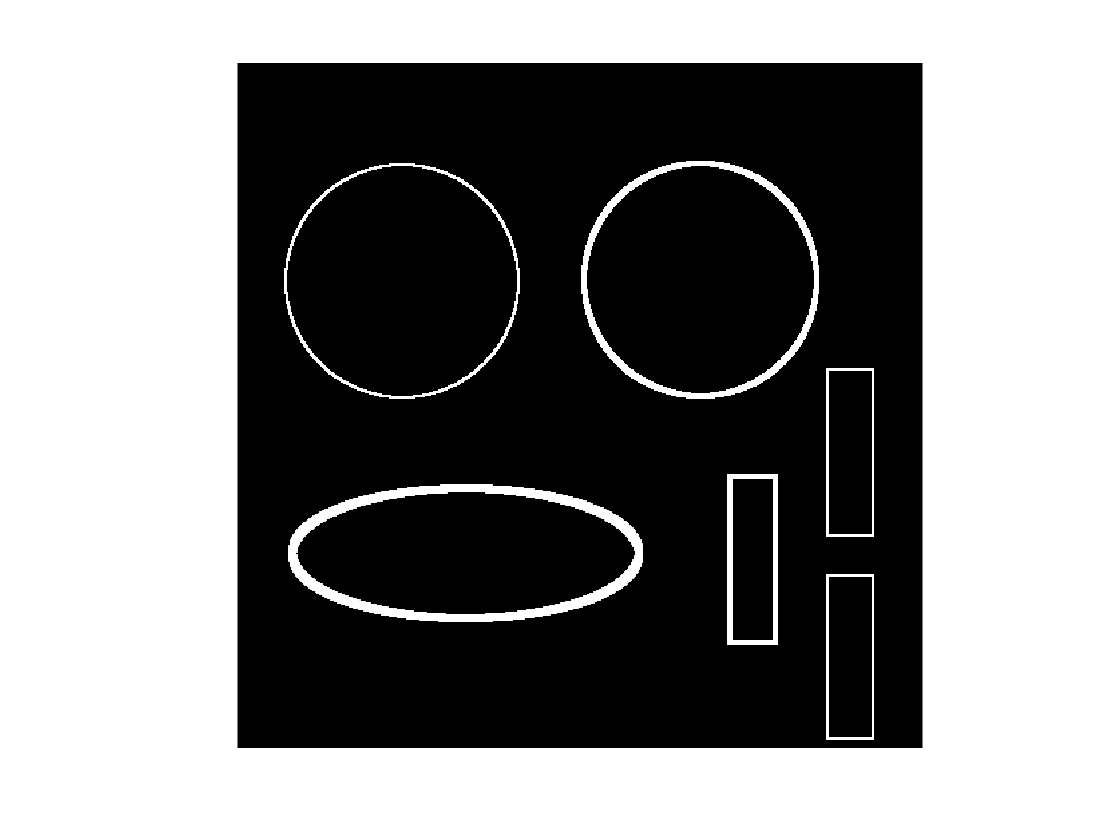

%ins Grauwert

max_Gmag=max(reshape(Gm,[1,512*512]));
Grauwert_Gmag=Gm/max_Gmag*255;
imshow(Grauwert_Gmag);

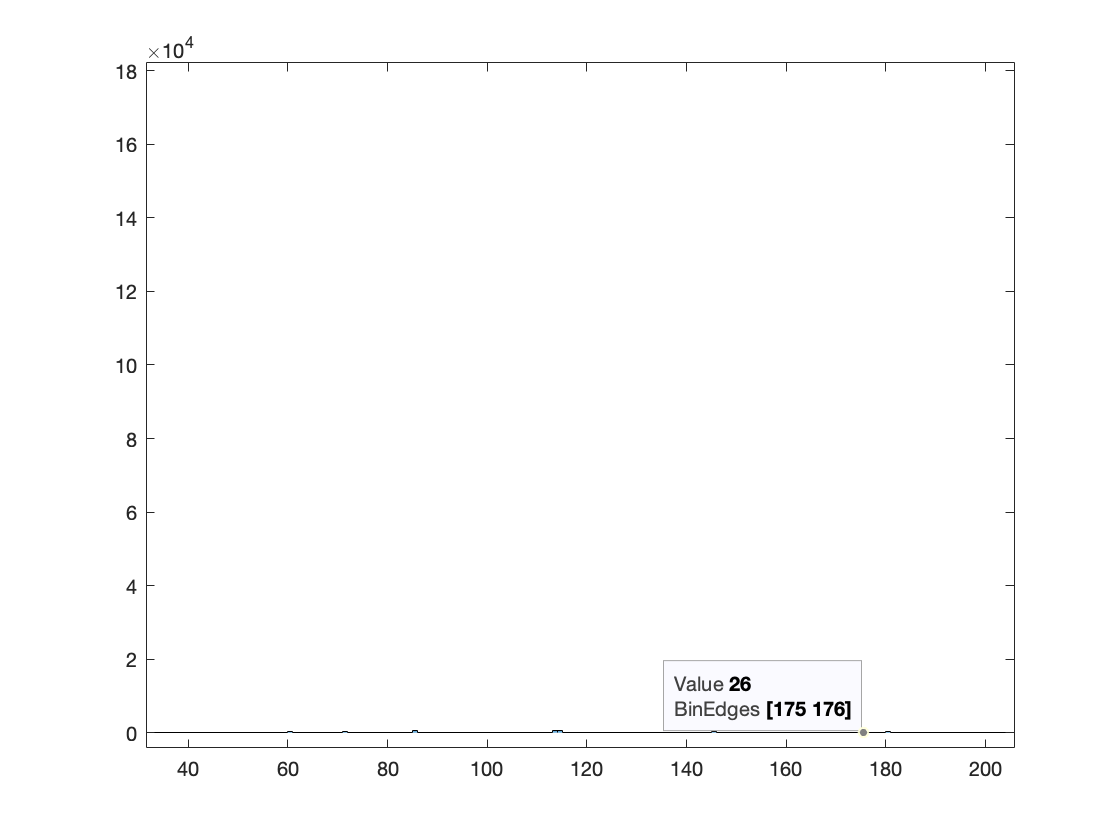

histogram(Grauwert_Gmag);

- Verwenden Sie jetzt die Funktion `edge`, um die Objekte 1 und 3 zu segmentieren

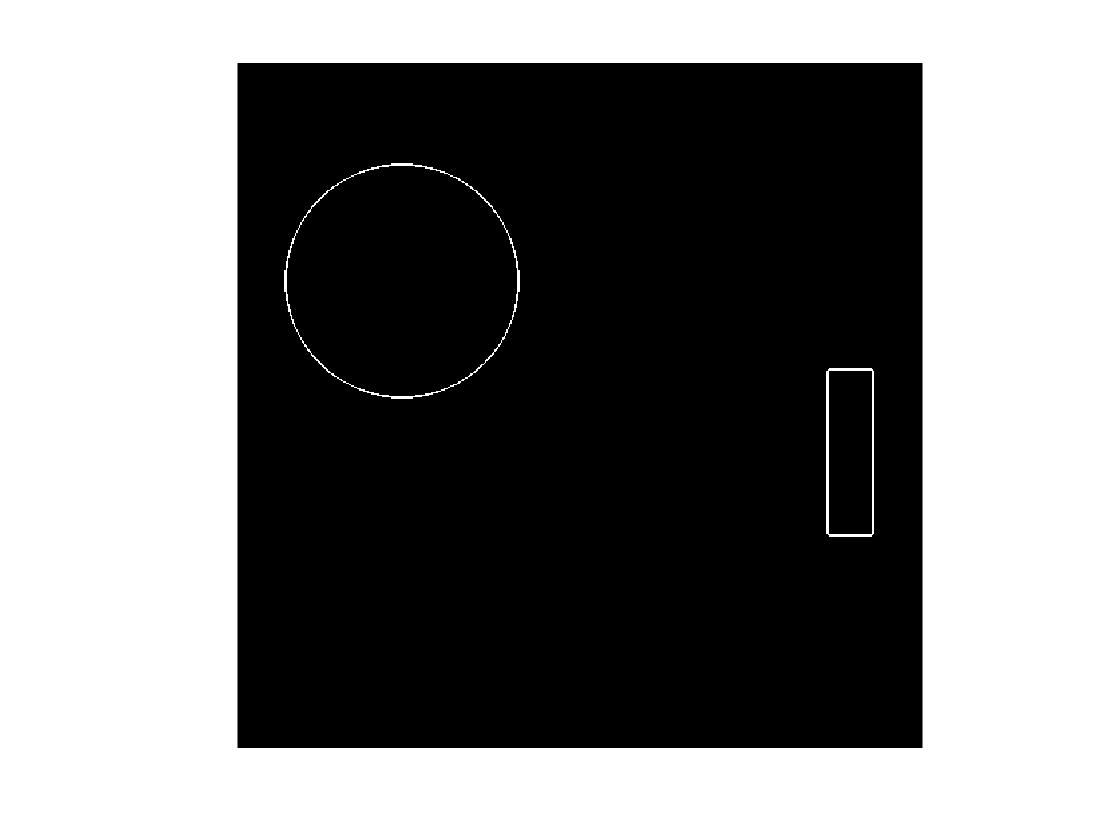

%einfach probieren und der Wert 192 ermitteln
temp=imbinarize(Grauwert_Gmag,192);
imshow(temp);

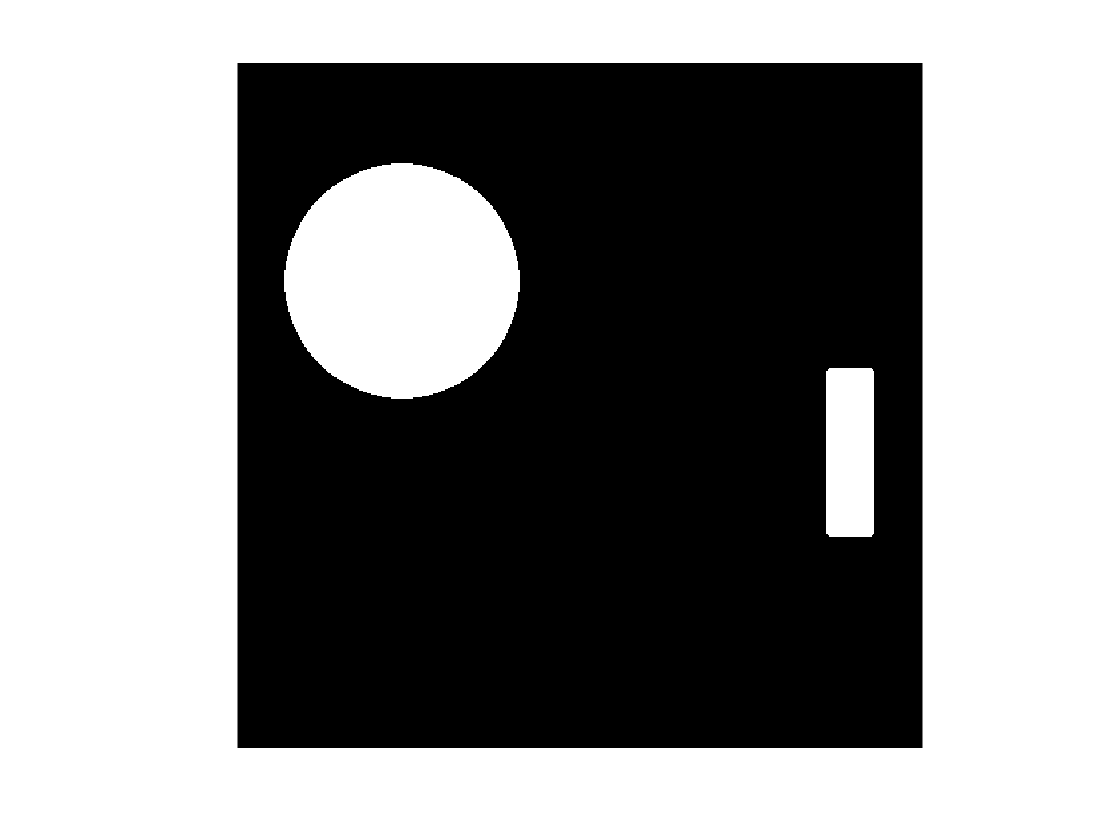

imshow(imfill(temp,"holes"));

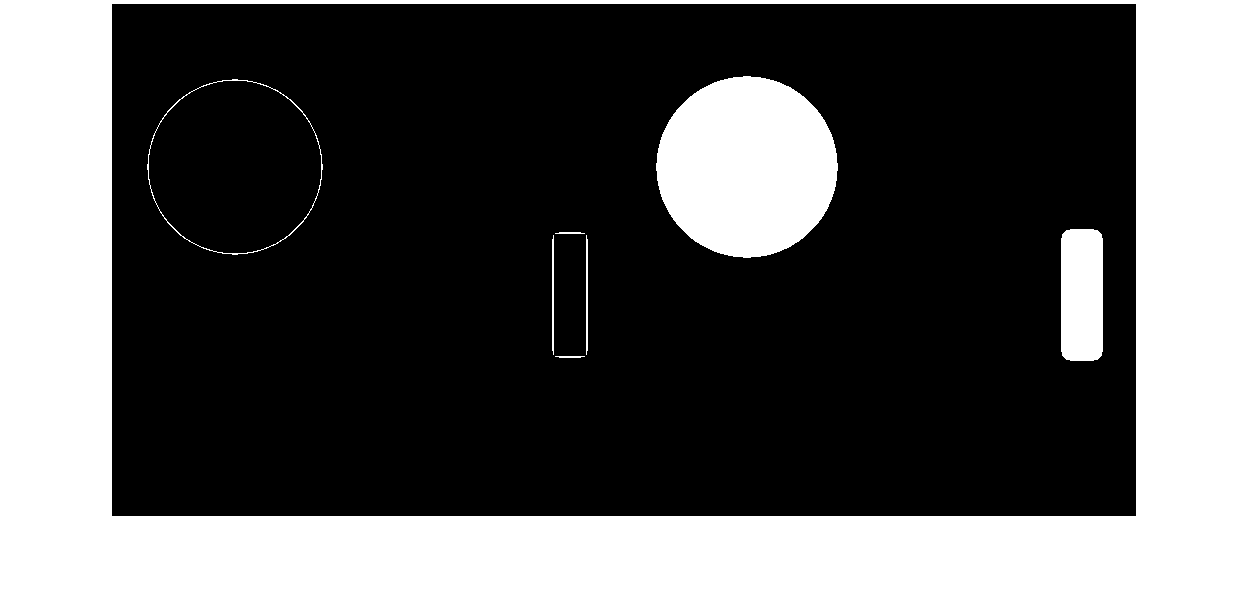

%Verwendung der Funktion EDGE
BW1_3=edge(img1,"canny",[0.9,0.92]); %canny hat 2 Grenze als eine METHODE
se=strel("disk",4);
imshowpair(BW1_3,imfill(imdilate(BW1_3,se),"holes"),"montage");

- Erstellen Sie ein Skript, das eine Segmentierung des Objektes 2 ermöglicht.

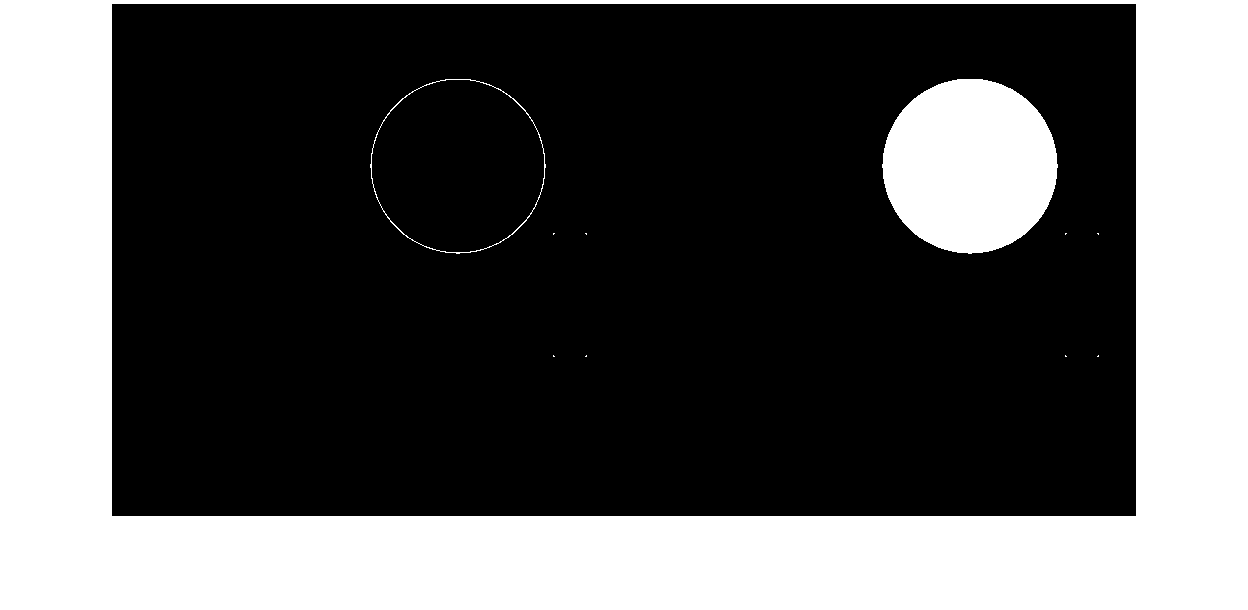

BW1_4=edge(img1,"canny",[0.90]);
imshowpair(BW1_4-BW1_3,imfill(BW1_4-BW1_3,"holes"),"montage");

**2.    Gradientenbasierte Segmentierung des Pumpengehäuses (20-30 Min)**

- Versuchen Sie nun mit Hilfe der neu erlernten Methoden die weiß umrandete Fläche des Pumpengehäuses (Bild1.png) zu segmentieren. 

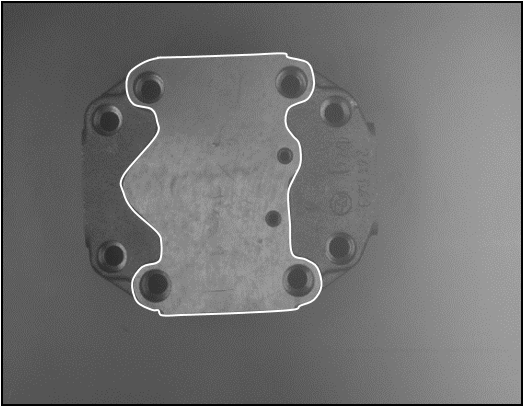

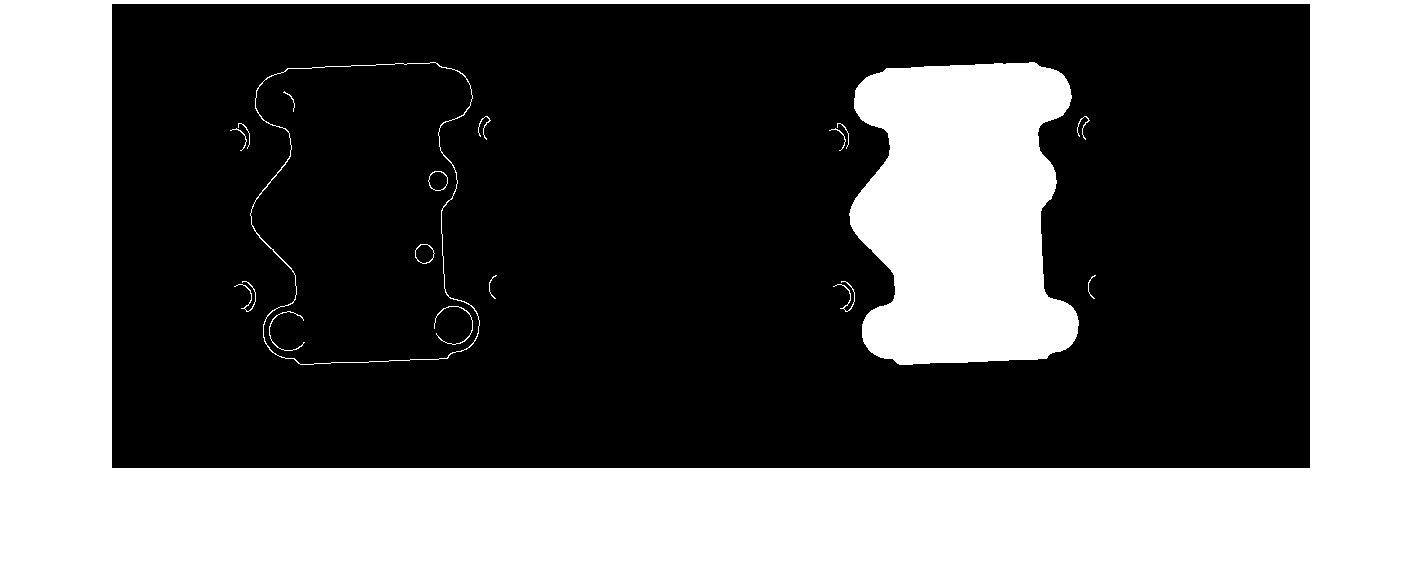

I=imread("/Users/tonystark/Desktop/TUB 2. Semester/BGA/Matlab-Files-20210107/Bild1.png");
BW_Pumpengehaeuse=edge(I,"Canny",(0.551));
imshowpair(BW_Pumpengehaeuse,imfill(BW_Pumpengehaeuse,"holes"),"montage");

- Ist es auch möglich, das Pumpengehäuse vollständig zu markieren? Welche Schwierigkeiten treten auf?

- Testen Sie Ihr Skript auch an dem etwas verschobenen Gehäuse in „Bild3“!

**3.    Vergleich Kantenfilter 1. Ordnung vs. Canny-Algorithmus (30-45 Min)**

- Um ein Gefühl für den Unterschied zwischen einem konventionellen Kantenfilter und dem Canny-Algorithmus zu bekommen, soll ein Script erstellt werden, das beide Operationen miteinander vergleicht. Verwenden Sie dazu die Funktion `edge` und wählen Sie als Methode `Canny` aus*. *Stellen Sie die Bilder mit dem konventionellen Kantenfilter und dem Canny-Algorithmus nebeneinander dar.

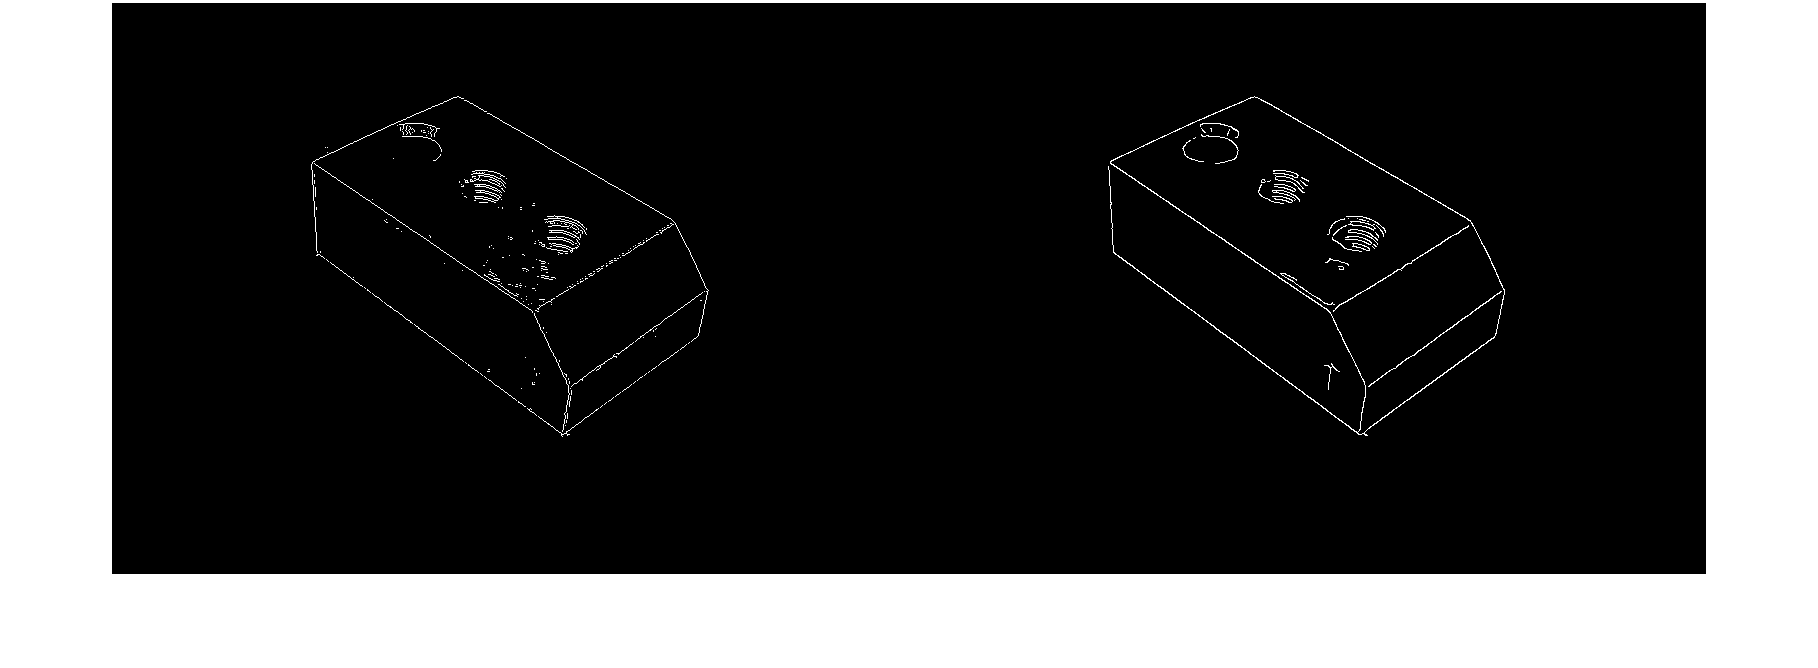

img2=imread("/Users/tonystark/Desktop/TUB 2. Semester/BGA/Matlab-Files-20210107/Platte1.png");
img2_grey=rgb2gray(img2);
edge_prewitt=edge(img2_grey,"prewitt");
edge_canny=edge(img2_grey,"canny",0.1);
imshowpair(edge_prewitt,edge_canny,"montage");

- Wenn Sie das Script nun ausführen, können Sie die beiden Varianten zur Kantendetektion vergleichen. Variieren Sie die Parameter und diskutieren Sie Ihre Beobachtungen. Können Sie die Vorteile des Canny-Algorithmus nachvollziehen?

- Schauen Sie sich auch das Bild „Platte1“ an – für dieses Objekt werden wir in der nächsten Übungseinheit eine Geradenerkennung auf der Basis des Kantenbildes durchführen.